# Parachute Shock Loads

A simple calculator to find the shock loads acting on a rocket upon chute release, both for the drogue and main chutes - find the theory here:

[https://wiki.imperial.ac.uk/display/IRW/Estimating+loads+on+shock+cords](https://wiki.imperial.ac.uk/display/IRW/Estimating+loads+on+shock+cords)

### Initialise

clear; clc;

g = 9.81;
m = 29;     % Rocket mass (kg) (~dry)

% Tension fraction - proportion of mass below & above the coupler
% Why is this relevant? More details on the wiki
s = 0.75;

% Velocities (ms-1) - adjust these based on OpenRocket values
VD1 = 60;   % Drogue deployment velocity
VT1 = 24;    % Also VD2 - Set as per SA-REQ
VT2 = 5;   % Ground-hit terminal velocity


### Output

% Drogue deployment
disp(double(s*m*g*(VD1/VT1)^2));

   1.3335e+03




% Main deployment
disp(double(s*m*g*(VT1/VT2)^2));

   4.9160e+03



### Drogue Chute - graphs

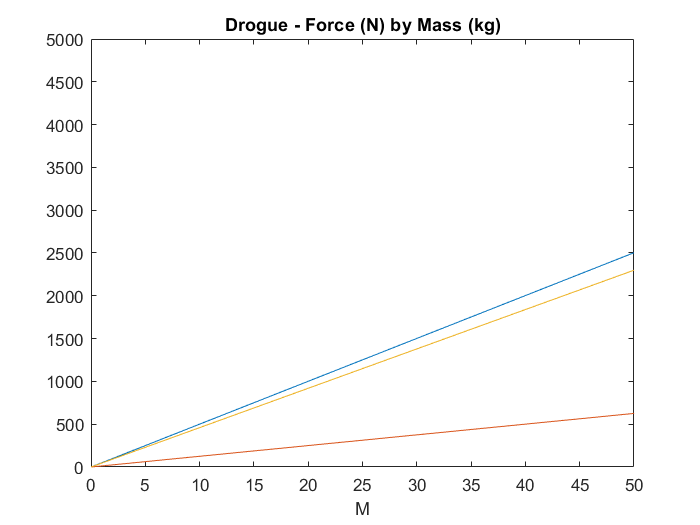

% Max loading
syms Dmax(M); Dmax(M) = s*M*g*(VD1/23)^2;

% Min loading
syms Dmin(M); Dmin(M) = s*M*g*(VD1/46)^2;

% For selected VT1
syms Dsel(M); Dsel(M) = s*M*g*(VD1/VT1)^2;


% Plotting graphs :)
ezplot(Dmax,[0,50,0,5000]);
hold on;
ezplot(Dmin,[0,50,0,5000]);
ezplot(Dsel,[0,50,0,5000]);
title("Drogue - Force (N) by Mass (kg)");
hold off;

### Main Chute - graphs

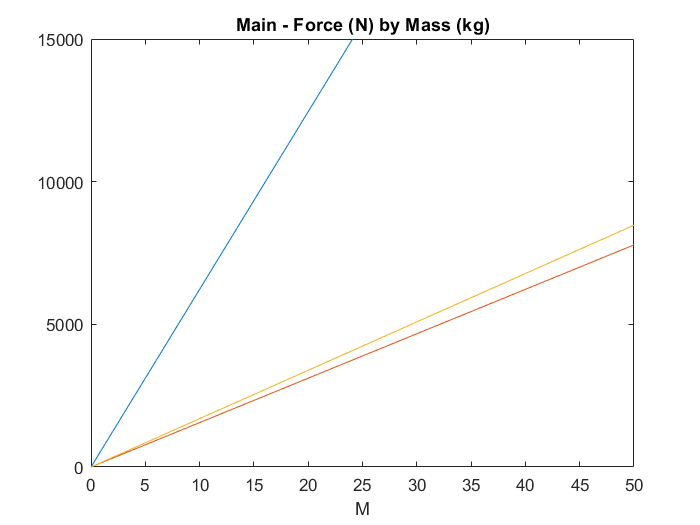

% Max loading
syms Mmax(M); Mmax(M) = s*M*g*(46/VT2)^2;

% Min loading
syms Mmin(M); Mmin(M) = s*M*g*(23/VT2)^2;

% For selected VT1
syms Msel(M); Msel(M) = s*M*g*(VT1/VT2)^2;

% Even more :)
ezplot(Mmax,[0,50,0,15000]);
hold on;
ezplot(Mmin,[0,50,0,15000]);
ezplot(Msel,[0,50,0,15000]);
title("Main - Force (N) by Mass (kg)");
hold off;